need to:

not hardcode pan and tilt

calibrate distance to voltage

use distance not voltage

also color close/far?

load('fullScan.mat');

Calibrate Distance to Voltage

calibrateData = [15, 2.75;
    20, 2.5;
    30, 2;
    40, 1.5;
    50, 1.25;
    60, 1.05;
    70, 0.9;
    80, 0.8;
    90, 0.75;
    100, 0.65
    110, 0.6
    120, 0.55
    130, 0.5];
calibrateDataDistance = calibrateData(:, 1);
calibrateDataVoltage = calibrateData(:, 2);
%cftool
a = 3.1121;
b = -0.0158;
x = linspace(0, 140, 140);
calCurve = a*exp(b*x);

figure(1)
hold on
plot(calibrateDataDistance, calibrateDataVoltage, "x")
plot(calCurve)
hold off

% outputDistance = a*exp(b*sensorData);

% nDegrees = 4;
% % out4x4 = reshape(sensorData, [4, 4])
% % %cut it into a 4 by 4
% 
% panValues = [0,0,0,0, 0.5,0.5,0.5,0.5, 1,1,1,1, 1.5,1.5,1.5,1.5]
% tiltValues = [0, 0.3, 0.6, 1, 0, 0.3, 0.6, 1, 0, 0.3, 0.6, 1, 0, 0.3, 0.6, 1]

Az = sensorData(3, :); % Azimuth - pan angle
El = sensorData(2, :); % Elevation - tilt angle
Rd = sensorData(1, :); % voltage data

cn = ceil(max(El));                                             % Number Of Colors
cm = colormap(jet(cn));


% for i = 1:length(Rd)
%     if Rd(i) > 1
%         Rd(i) = 0;
%          Az(i) = 0;
%          El(i) = 0;
%     else 
%         disp("else")
%     end
% end



[x,y,z]=sph2cart (Az,El,Rd)

x =          0    2.5953    2.7271    2.5948    2.5892    2.5590    2.5578    2.4978    2.5498    2.5868    2.5797    2.4411    2.3461    2.2124    2.2241    2.1533    2.2419    2.2190    2.0659    1.9997    1.8376    1.9201    1.8300    1.8259    1.6599    1.3854    1.4860    1.3924    1.2897    1.1827    1.1558    0.8910    0.8881    0.7415    0.7205    0.6305    0.6236    0.6030    0.6188    0.5438    0.4694    0.5393    0.5682    0.5702    0.5498    0.5648    0.5797    0.5418    0.5869    0.5232


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


z =          0         0    0.0275    0.0524    0.0785    0.1035    0.1293    0.1516    0.1806    0.2095    0.2352    0.2474    0.2618    0.2695    0.2937    0.3065    0.3423    0.3618    0.3583    0.3676    0.3571    0.3933    0.3941    0.4126    0.3927    0.3426    0.3834    0.3743    0.3607    0.3437    0.3486    0.2786    0.2876    0.2484    0.2495    0.2255    0.2301    0.2295    0.2427    0.2196    0.1951    0.2306    0.2498    0.2575    0.2550    0.2690    0.2833    0.2716    0.3016    0.2756


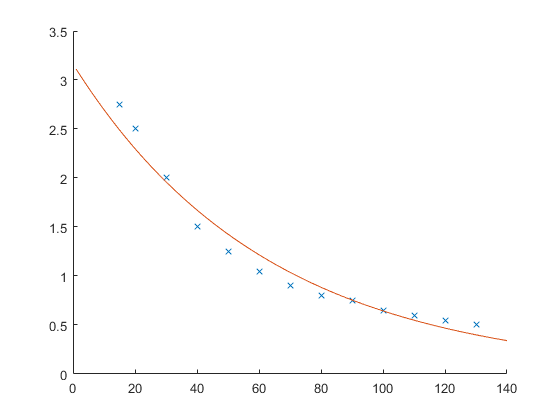

% plot3(x,y,z,'o')

% zscaled = z                                                 % May Be Necessary To Scale The Colour Vector
% cn = ceil(max(zscaled));                                        % Number Of Colors (Scale AsAppropriate)
% cm = colormap(jet(cn));                                         % Define Colormap
cm = colormap(jet(cn));                                         % Define Colormap

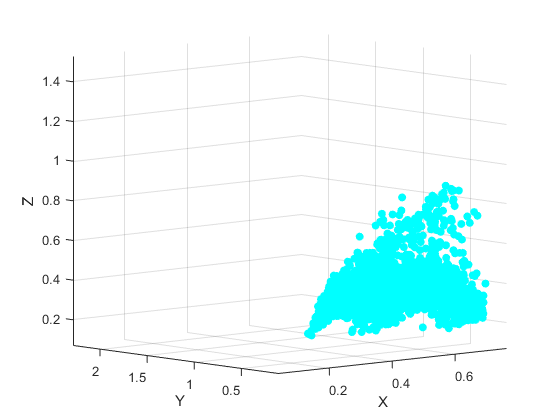


%ahhhhhh = cm(ceil(zscaled),:)

% scatter3(x,y,z)
% scatter3(x, y, z, [])
% scatter3(x, y, z, [], cm)
% for i=1:length(x(1,:))
%     if x(1,i) > .7
%         x(1,i) = 0;
%     end
% end
figure (2)
scatter3(x, y, z, [], cm, 'filled')
xlabel('X')
ylabel('Y')
zlabel('Z')

% scatter3(0, 0, 0, 5, "r")